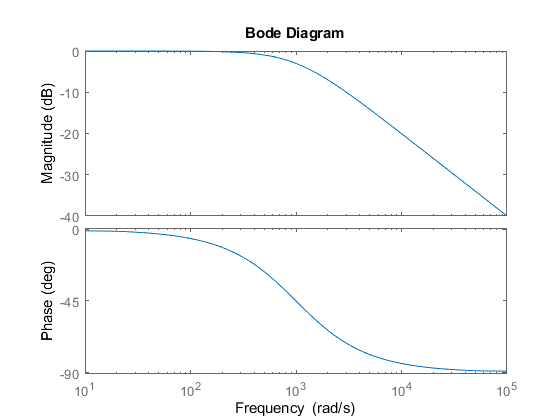

R = 100;
C = 10e-6;

s = tf('s');

T = 1/(R*C*s+1);

bode(T)

w = 1/(R*C);

[mag,phase] = bode(T,w)

mag = 0.7071

phase = -45

Ts = 1e-4;
Tp = 1e-1;

out = sim('Week14a_sim.slx')

out =   Simulink.SimulationOutput:

                   tout: [2001x1 double] 
                      u: [2001x1 double] 
                      v: [2001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


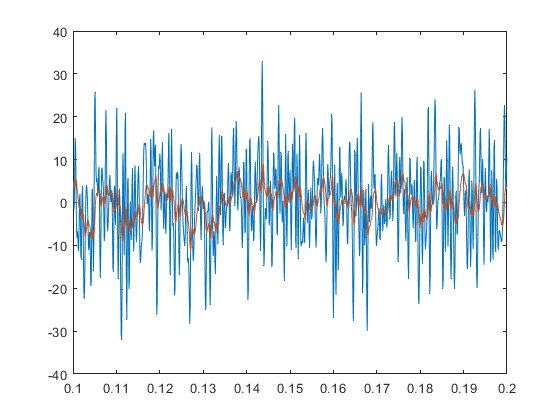


t = out.tout;

u = out.u(t>t(end)-Tp);
v = out.v(t>t(end)-Tp);
t = t(t>t(end)-Tp);

plot(t,u,t,v)

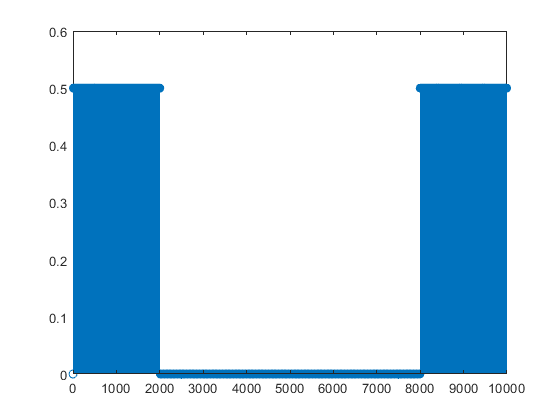

f = 0:1/Tp:1/Ts-1/Tp;

U = fft(u/length(u));
stem(f,abs(U))

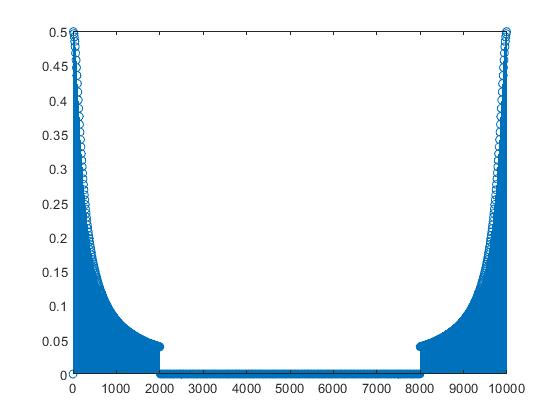

V = fft(v/length(v));
stem(f,abs(V))

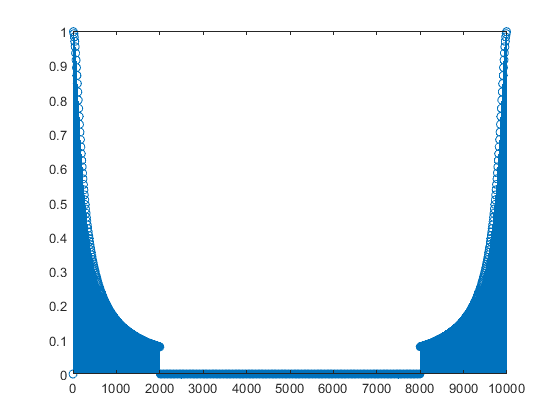

Texp = V./U;
Texp(abs(U)<0.1)=0;
stem(f,abs(Texp))

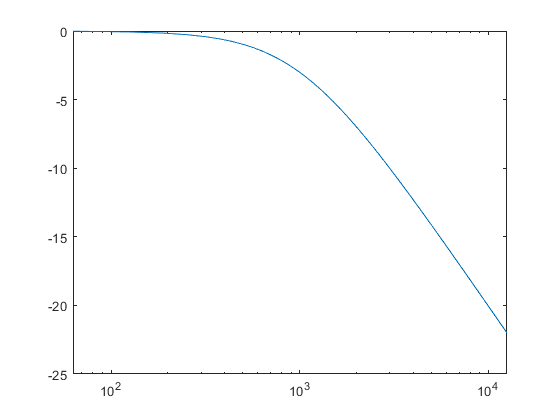

semilogx(2*pi*f(f<.5/Ts),db(abs(Texp(f<.5/Ts))))